clear all;close all;

% mo=load('C:\Users\sgrc-325\Desktop\git\pipes\data\1014_0.CSV');  %cigu 0.7m 12v runtest
% mo=load('C:\Users\sgrc-325\Desktop\git\pipes\data\1029_8.CSV');  %DOHZ 2~10hz 0.7m 12v 24v
% mo=load('C:\Users\sgrc-325\Desktop\git\pipes\data\1030_0.CSV');  %DOHZ h1 test
% mo=load('C:\Users\sgrc-325\Desktop\git\pipes\data\1030_1.CSV');  %DOHZ 3、4hz 0.7m 6v 12v 24v
mo=load('C:\Users\sgrc-325\Desktop\git\pipes\data\1101_1.CSV');  %DOHZ car run 4hz*2 0.7m 12v 24v

mo=mo(389000:392000,:);
moo=mo;

mo=moo(:,[1:17]);
% mo(1,:)=[];

[No,~]=size(moo);
t0=[1 No];
t=moo(:,1);
[a1 a3]=size(moo);
[a1 a2]=size(mo);
f=moo(:,a3); %freqency
mo_cor=zeros(a1,a2);
% mo_cor=mo;

% mo(a1-200:a1,:)=[];
t=mo(:,1);

% mo_cor(:,1)=mo(:,1);
% for i=1:a1   %校正數據
%     mo_cor(i,2:4)=(Ta*Ka*(mo(i,2:4)'+Ba))';
%     mo_cor(i,5:7)=(Tg*Kg*(mo(i,5:7)'+Bg))';
%     mo_cor(i,8:10)=(Tm2a*(mo(i,8:10)'+Bm))';
%     mo_cor(i,11:13)=(Tm2a_2*(mo(i,11:13)'+Bm_2))';
% end

% acc1 = mo_cor(:,2:4);  %有校正
% gyr=mo_cor(:,5:7);
% % acc2 = mo_cor(:,5:7);
% m = mo_cor(:,8:10)*0.01;   %%%% to guess
% m2 = mo_cor(:,11:13)*0.01;   %%%%

acc1 = mo(:,3:5);  %無校正
acc2 = mo(:,6:8);  %無校正
gyr1=mo(:,9:11);
gyr2=mo(:,12:14);
m = mo(:,15:17); %%%% to guess
temp=moo(:,20:23);
h1=moo(:,18);
h2=moo(:,19);
magt=moo(:,20);
imu1t=moo(:,21);
imu2t=moo(:,22);
mcut=moo(:,23);
f=moo(:,24);
delay=moo(:,25);
ax1=acc1(:,1);ay1=acc1(:,2);az1=acc1(:,3);
ax2=acc2(:,1);ay2=acc2(:,2);az2=acc2(:,3);
aGo=sqrt(mo_cor(:,2).^2+mo_cor(:,3).^2+mo_cor(:,4).^2);
aG=sqrt(ax1.^2+ay1.^2+az1.^2);
aG2=sqrt(ax2.^2+ay2.^2+az2.^2);
GG=sqrt(gyr1(:,1).^2+gyr1(:,2).^2+gyr1(:,3).^2)*0.01;
GG2=sqrt(gyr2(:,1).^2+gyr2(:,2).^2+gyr2(:,3).^2)*0.01;
mm4=sqrt(m(:,1).^2+m(:,2).^2+m(:,3).^2);
% mm42=sqrt(m2(:,1).^2+m2(:,2).^2+m2(:,3).^2);
stdd=std(mo)'; %看標準差
stdd_cor=std(mo_cor)';

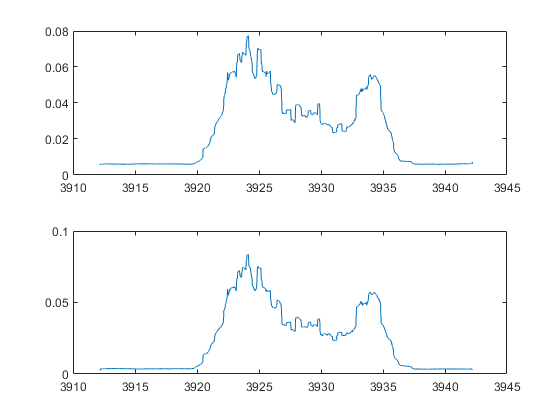

close all
figure(1)
subplot(2,1,1)
plot(t,smooth(GG,200))
subplot(2,1,2)
plot(t,smooth(GG2,200))

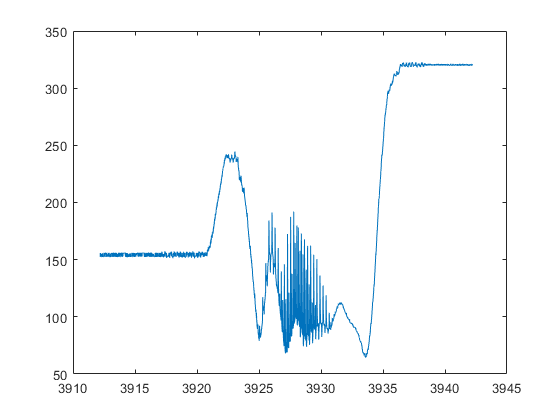


figure(2)
plot(t,mm4)

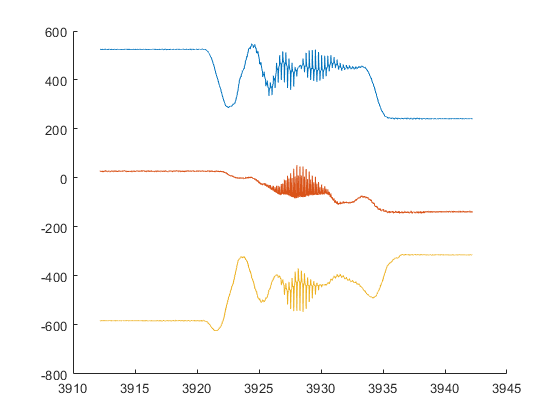


figure(3)
% plot(t,m)
hold on
plot(t,m(:,1)+500)
plot(t,m(:,2)-100)
plot(t,m(:,3)-500)
hold off

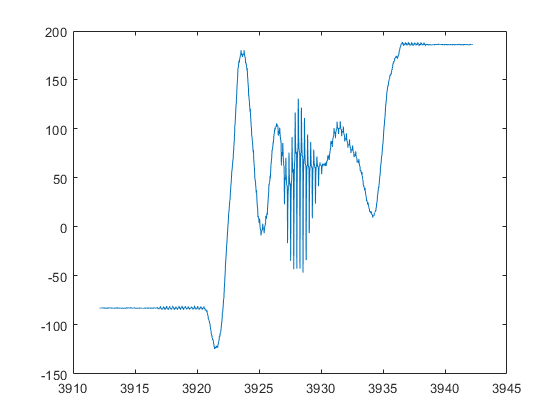


figure(4)
% plot(t,m(:,1))
% plot(t,m(:,2))
plot(t,m(:,3))

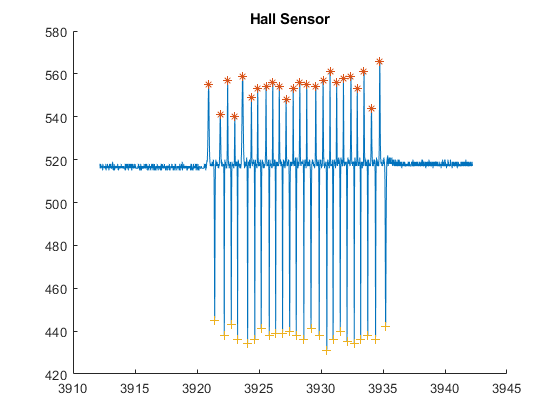

close all
addpath('C:\Users\sgrc-325\Desktop\git\matlabs');
% h2t=[t(389000:392000) h2(389000:392000)]
h2t=[t h2];
[DfromH,VfromH,AfromH,AV] = Encoder_3f(h2t,70);

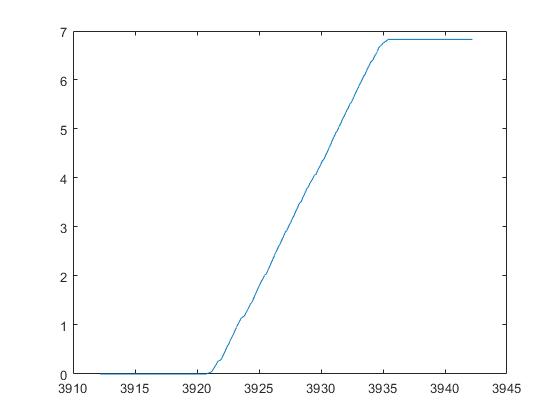


figure(2)
% plot(t(389000:392000),DfromH)
plot(t,DfromH)


% figure(3)
% plot(t,VfromH)

fprintf('end position : %.5f m\n', DfromH(end));

end position : 6.83038 m


fprintf('average velocity : %.5f m/s\n', mean(AV));

average velocity : 0.46225 m/s


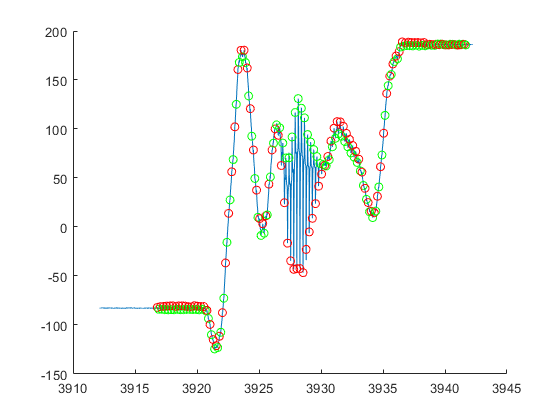

close all

tt1=3916.8; %開始時間
tt2=tt1+0.115;
hz=4; %hz
long=25*4; %peak 數
tn=tt1+long;
ticks(1:long)=0;
for i=1:long
    ticks(i)=tt1+(i-1)*(1/hz);
    ticks2(i)=tt2+(i-1)*(1/hz);
end
tickss=ticks;
tickss2=ticks2;
for i=1:long
    [~,tickss(i)]=min(abs(t-ticks(i))); %find the position of the time
    [~,tickss2(i)]=min(abs(t-ticks2(i))); %find the position of the time
end
paxis=3;

figure(1)
hold on
plot(t,m(:,paxis))
for i=1:long
    plot(ticks(i),m(tickss(i),paxis),'ro')
    plot(ticks2(i),m(tickss2(i),paxis),'go')
end
hold off

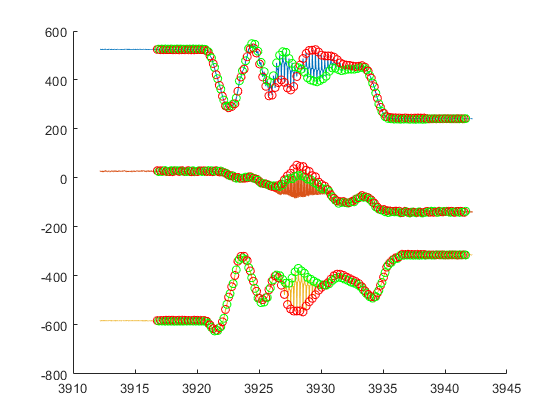


figure(2)
hold on
% plot(t,m)
plot(t,m(:,1)+500)
plot(t,m(:,2)-100)
plot(t,m(:,3)-500)
for i=1:long
    plot(ticks(i),m(tickss(i),1)+500,'ro')
    plot(ticks(i),m(tickss(i),2)-100,'ro')
    plot(ticks(i),m(tickss(i),3)-500,'ro')
    plot(ticks2(i),m(tickss2(i),1)+500,'go')
    plot(ticks2(i),m(tickss2(i),2)-100,'go')
    plot(ticks2(i),m(tickss2(i),3)-500,'go')
end
hold off

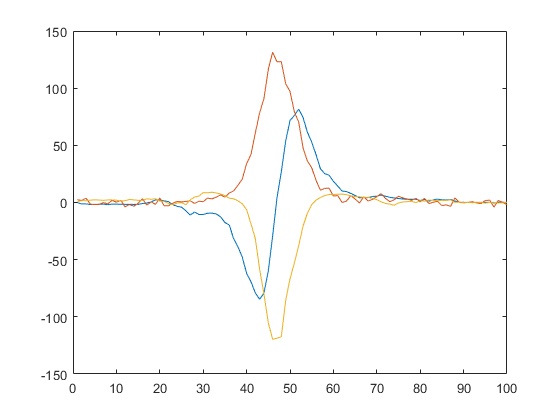

% got m from peak
gotb1=[];gotb2=[];gotm1=[];gotm2=[];
gotb1(long,3)=zeros;
gotb2(long,3)=zeros;
gotm1(long,3)=zeros;
gotm2(long,3)=zeros;

fk=-4;
bk=8;

for i=1:long
    gotb1(i,:)=(m(tickss(i)+fk,:)+m(tickss(i)+bk,:))/2;
    gotb2(i,:)=(m(tickss2(i)+fk,:)+m(tickss2(i)+bk,:))/2;
end

for i=1:long
    gotm1(i,:)=m(tickss(i),:)-gotb1(i,:);
    gotm2(i,:)=m(tickss2(i),:)-gotb2(i,:);
end

figure(1)
plot(gotm1)

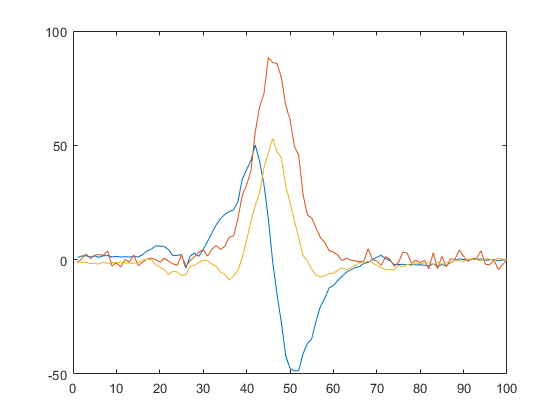

figure(2)
plot(gotm2)

% %% threshold filter waves (for pipe measuring)
% close all  %old波峰波谷
% 
% % T0=1106700; %481.5cm 36v 1.4m
% % T1=1119000;
% T0=1177000; %481.5cm 36v 1.4m
% T1=1182000;
% 
% x=m(:,1);
% y=m(:,2);
% z=m(:,3);
% 
% waveN=75;
% useddata=z; % 用來判斷的數據
% filtCutOff = 0.8; % 高通判斷數據使可判斷波峰谷
% [b, a] = butter(1, (2*filtCutOff)/(1/0.01), 'low');
% useddataL = filtfilt(b, a, useddata);
% 
% 
% testdata=useddataL(T0:T1);
% IndMin=find(diff(sign(diff(testdata)))>0);  %獲得局部最小值的位置(可微調位置
% IndMax=find(diff(sign(diff(testdata)))<0)-1;  %獲得局部最大值的位置
% 
% magmin=IndMin; % 彌補時間差
% magmax=IndMax;
% 
% hold on
% % plot(useddata)
% % plot(useddataL)
% % plot(magmin+T0,useddata(magmin+T0),'r^') % 標示在原數據 彌補時間差
% % plot(magmax+T0,useddata(magmax+T0),'k*')
% 
% plot(useddata(T0:T1))
% plot(useddataL(T0:T1))
% plot(magmin,useddata(magmin+T0),'r^') % 標示在原數據 彌補時間差
% plot(magmax,useddata(magmax+T0),'k*')
% 
% tag=[magmax magmin]; % 檢查位置
% tag=reshape (tag, 1, numel(tag));
% tag=sort(tag,'ascend');
% set(gca, 'xtick', tag);
% grid on
% 
% magmax=magmax+T0;
% magmin=magmin+T0;
% 
% for i=1:waveN %每個位置磁力平均值
%     wxa(i)=x(magmax(i));wxb(i)=x(magmin(i));
%     wya(i)=y(magmax(i));wyb(i)=y(magmin(i));
%     wza(i)=z(magmax(i));wzb(i)=z(magmin(i));
%     
%     wx(i)=x(magmax(i))-x(magmin(i));
%     wy(i)=y(magmax(i))-y(magmin(i));
%     wz(i)=z(magmax(i))-z(magmin(i));
% 
%     ew(i)=sqrt(mean(wx(i))^2+mean(wy(i))^2+mean(wz(i))^2);
% end
% ews=[wx wy wz];
% % ew
% % mean(ews)
% % mean(ew)
% 
% pw=mean(wza)
% pw2=mean(wzb)
% kk=[1 T1-T0;pw pw]';
% plot(kk(:,1),kk(:,2))
% kk2=[1 T1-T0;pw2 pw2]';
% plot(kk2(:,1),kk2(:,2))
% hold off
